# **Command -- Merbouche Mouloud & Tso Célia **

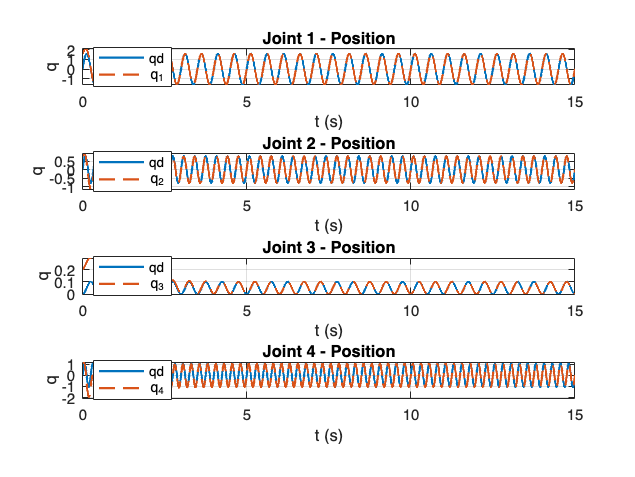

clear
close all
clc

load joint_traj.mat;
N = length(t);

qdp  = dqd;
qdpp = ddqd;

q   = zeros(4, N);
qp  = zeros(4, N);
qpp = zeros(4, N);

q(:,1)  = [pi/2; pi/4; 0.2;  pi/3];
qp(:,1) = [pi^2/2; pi^2/4; 0.3; pi^2/3];

%Kd = eye(4);
%Kp = eye(4);
Kd = 10*eye(4);
Kp = 10*eye(4);
%Kd = 50*eye(4);
%Kp = 50*eye(4);
for mm = 2:length(t)

    qpp(:,mm) = qdpp(:,mm) ...
              + Kd * ( qdp(:,mm-1) - qp(:,mm-1) ) ...
              + Kp * ( qd(:,mm-1)  - q(:,mm-1)  );

    qp(:,mm) = qp(:,mm-1) + qpp(:,mm) * dt;
    q(:,mm)  = q(:,mm-1)  + qp(:,mm)  * dt;

end


%% Plot superposé entre la position désirée qd et q puis qp et dqd et ddqd vs qpp

figure('Name','Positions: q vs qd','NumberTitle','off');
for i = 1:4
    subplot(4,1,i);
    plot(t, qd(i,:), 'LineWidth', 1.5); hold on;
    plot(t, q(i,:),  '--', 'LineWidth', 1.5);
    grid on;
    xlabel('t (s)');
    ylabel(sprintf('q', i));
    legend(sprintf('qd', i), sprintf('q_%d', i), 'Location','best');
    title(sprintf('Joint %d - Position', i));
end

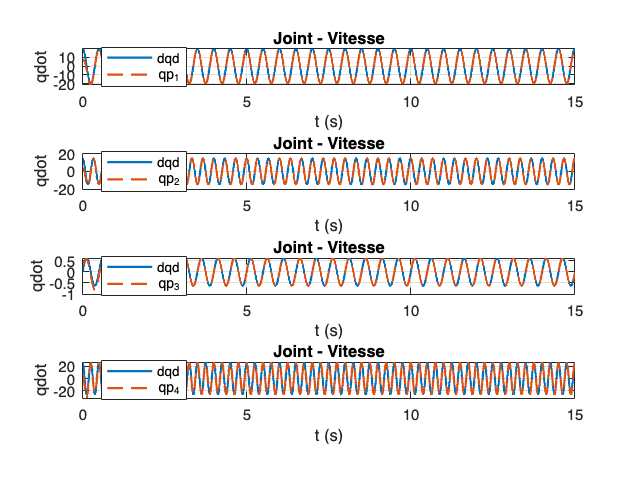


figure('Name','Velocities: qp vs dqd','NumberTitle','off');
for i = 1:4
    subplot(4,1,i);
    plot(t, dqd(i,:), 'LineWidth', 1.5); hold on;
    plot(t, qp(i,:),  '--', 'LineWidth', 1.5);
    grid on;
    xlabel('t (s)');
    ylabel(sprintf('qdot', i));
    legend(sprintf('dqd', i), sprintf('qp_%d', i), 'Location','best');
    title(sprintf('Joint - Vitesse', i));
end

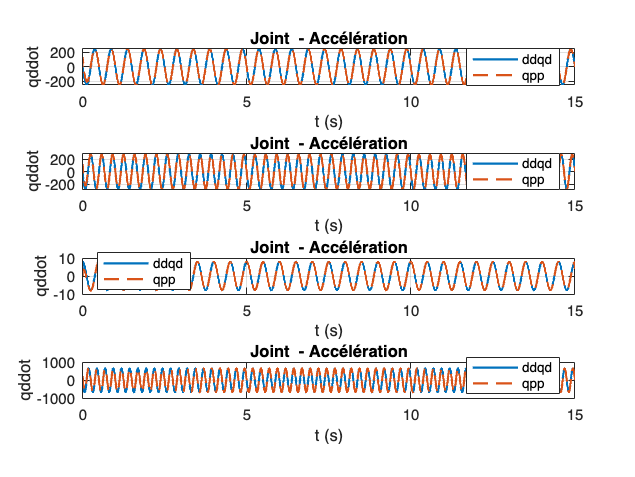


figure('Name','Accelerations: qpp vs ddqd','NumberTitle','off');
for i = 1:4
    subplot(4,1,i);
    plot(t, ddqd(i,:), 'LineWidth', 1.5); hold on;
    plot(t, qpp(i,:),  '--', 'LineWidth', 1.5);
    grid on;
    xlabel('t (s)');
    ylabel(sprintf('qddot', i));
    legend(sprintf('ddqd', i), sprintf('qpp', i), 'Location','best');
    title(sprintf('Joint  - Accélération', i));
end